Ua = 400;
Ra = 21.45;  %not have
dfi = 0.39; 

Trated = 35;
Ta = 3; 
Ke = 8;
J1 = 0.125;
J2 = 0.063;
k12 = 1675;

Tref = 0.1*Trated;
Tmdl = 10;

warning off
Simout = sim('lab1.slx','ReturnWorkspaceOutputs','on');
warning on

Transient response of w1and w2

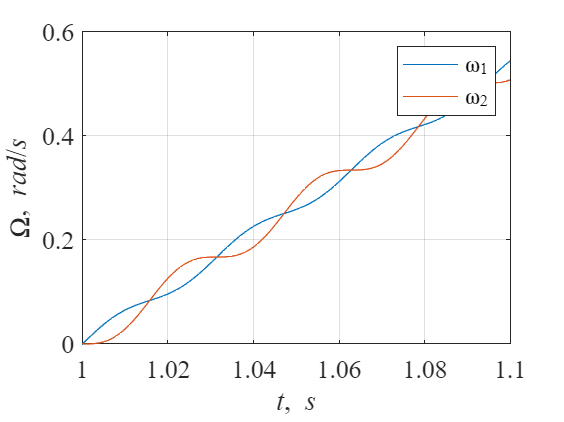

t = Simout.w12(:,1);
w1 = Simout.w12(:,2);
w2 = Simout.w12(:,3);

h = figure;
    set(h,'DefaultAxesFontSize',14);
    set(h,'DefaultAxesFontName','Times New Roman');
    plot(t,w1)
    grid on
    hold on
    plot(t,w2)
    ylabel('\Omega, \itrad\rm/\its')
    xlabel('\itt\rm, \its')
    legend('\omega_1','\omega_2')
    xlim([1 1.1])

Transient response of T12

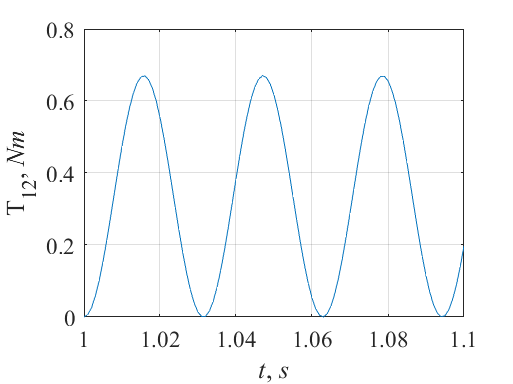

t = Simout.w12(:,1);
T12 = Simout.w12(:,4);

h = figure;
    set(h,'DefaultAxesFontSize',14);
    set(h,'DefaultAxesFontName','Times New Roman');
    plot(t,T12)
    grid on
    hold on
    ylabel('T_{12}, \itNm')
    xlabel('\itt\rm, \its')
    xlim([1 1.1])